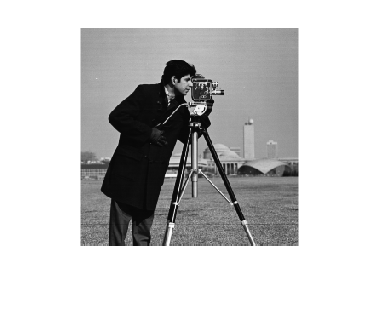

f=imread('cameraman.tif');
imshow(f)

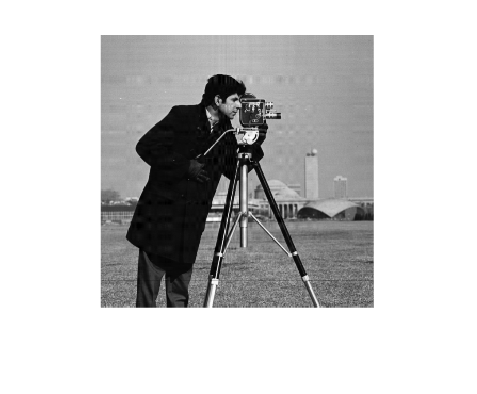

f=double(f);   %uint8无法svd,要double
[u,s,v]=svd(f);  %奇异值分解
s=diag(s);  %提对角元素得向量
s1=s;
s1(21,end)=0;   %只保留前20大的奇异值
s1=diag(s1);
g=u*s1*v';    %图像压缩
g=uint8(g);

imshow(g)